# FMCW Range estimation - Multiple Targets

Resolution = c/2B = 0.0375 m

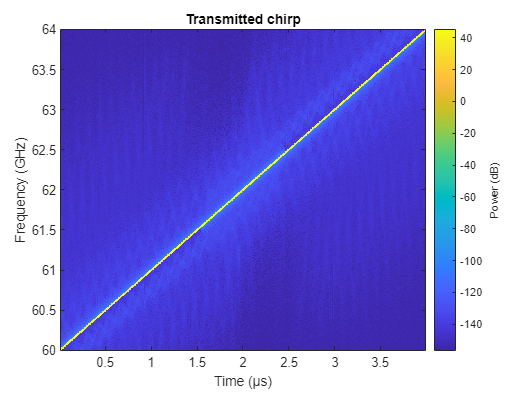

fs = 160e9; %Sampling frequency 10 GHz
ts = 1/fs; %Sampling interval
L = 160000*4;
t = (0:L-1)*ts; %Time vector
l = length(t);
f = fs*(-l/2:l/2-1)/l;

f1 = 60*10^9; %Minimum frequency
f2 = 64*10^9; %Maximum frequency
K = 1e15; %Chirp slope
x = 100*cos(2*pi*f1*t + pi*K*t.^2); %Sawtooth FMCW
c = 3*10^8;
d1 = 6.64005; %Distance
td1 = 2*d1/c; %Round trip delay

d2 = 6.981404;
td2 = 2*d2/c;

d3 = 6.324555;
td3 = 2*d3/c;

d4 = 3.720215;
td4 = 2*d4/c;

d5 = 6.748303;
td5 = 2*d5/c;

y1 = (delayseq(x',td1,fs))'; %recieved chirp
y2 = (delayseq(x',td2,fs))';
y3 = (delayseq(x',td3,fs))';
y4 = (delayseq(x',td4,fs))';
y5 = (delayseq(x',td5,fs))';

figure();
pspectrum(x,fs,'spectrogram','Reassign',true,'FrequencyLimits',[60*10^9,64*10^9],'Reassign',true);
title('Transmitted chirp');

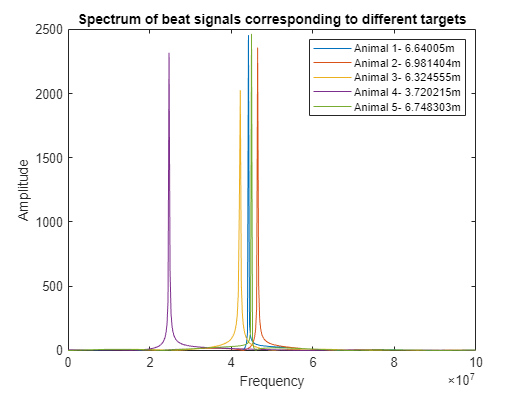

beat_1 = dechirp(y1',x');
beat_2 = dechirp(y2',x');
beat_3 = dechirp(y3',x');
beat_4 = dechirp(y4',x');
beat_5 = dechirp(y5',x');

beat_fft_1 = fftshift(fft(beat_1));
beat_fft_2 = fftshift(fft(beat_2));
beat_fft_3 = fftshift(fft(beat_3));
beat_fft_4 = fftshift(fft(beat_4));
beat_fft_5 = fftshift(fft(beat_5));

plot(f,abs(beat_fft_1/l),f,abs(beat_fft_2/l),f,abs(beat_fft_3/l),f,abs(beat_fft_4/l),f,abs(beat_fft_5/l));
legend('Animal 1- 6.64005m','Animal 2- 6.981404m','Animal 3- 6.324555m','Animal 4- 3.720215m','Animal 5- 6.748303m');
title("Spectrum of beat signals corresponding to different targets");
xlabel('Frequency');ylabel('Amplitude');
xlim([0,1e8]);

## MAP

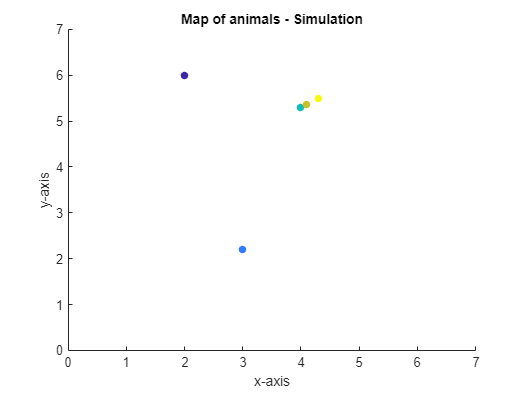

figure();
%sz = [1,2,3,4,5];
x_points = [2,3,4,4.1,4.3];
y_points = [6,2.2,5.3,5.36,5.5];
c = linspace(1,10,length(x_points));
scatter(x_points,y_points,[],c,'filled');
title('Map of animals - Simulation')
xlabel('x-axis');ylabel('y-axis');
axis([0,7,0,7]);